We need to take 50-100 images of our faces to have data sets!

**Folder location for the data set for easy changing**

DatasetFolder = 'C:\Users\EliteBook\OneDrive\Desktop\DSP\Image-recognition\FaceDataset_CROPPED'

DatasetFolder = 'C:\Users\EliteBook\OneDrive\Desktop\DSP\Image-recognition\FaceDataset_CROPPED'

**Create an image datastore**

imds = imageDatastore(DatasetFolder, ...
    "IncludeSubfolders", true, ... % Allow searching in subfolders
    'LabelSource', 'foldernames') % Assign labels on images based on the folders

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8642_face_4.JPG';
                              ' ...\Desktop\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8643.JPG';
                              ' ...\Desktop\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8644.JPG'
                               ... and 147 more
                              }
                     Folders: {
                              ' ...\EliteBook\OneDrive\Desktop\DSP\Image-recognition\FaceDataset_CROPPED'
                              }
                      Labels: [Filipa; Filipa; Filipa ... and 147 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"

**Split data into training and validation sets**

- imdsTrain object will receive 70% of the images for training

- imdsValidation object will receive the remaining 30% of the images for validation during training

[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.7, 'randomized')

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8642_face_4.JPG';
                              ' ...\Desktop\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8644.JPG';
                              ' ...\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8645_face_6.JPG'
                               ... and 102 more
                              }
                     Folders: {
                              ' ...\EliteBook\OneDrive\Desktop\DSP\Image-recognition\FaceDataset_CROPPED'
                              }
                      Labels: [Filipa; Filipa; Filipa ... and 102 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "

imdsValidation =   ImageDatastore with properties:

                       Files: {
                              ' ...\Desktop\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8643.JPG';
                              ' ...\Desktop\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8658.JPG';
                              ' ...\DSP\Image-recognition\FaceDataset_CROPPED\Filipa\IMG_8668_face_6.JPG'
                               ... and 42 more
                              }
                     Folders: {
                              ' ...\EliteBook\OneDrive\Desktop\DSP\Image-recognition\FaceDataset_CROPPED'
                              }
                      Labels: [Filipa; Filipa; Filipa ... and 42 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputForma

countEachLabel(imdsTrain)

ans = 3×2 table
     Label     Count
    _______    _____

    Filipa      35  
    Ignas       35  
    Vakaris     35  


countEachLabel(imdsValidation)

ans = 3×2 table
     Label     Count
    _______    _____

    Filipa      15  
    Ignas       15  
    Vakaris     15  


**Load pretrained network and define network input size**

net = resnet50

net =   DAGNetwork with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}


analyzeNetwork(net)
inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


**Prepare network for transfer learning**

lgraph = layerGraph(net) % Object to allow modification of network

lgraph =   LayerGraph with properties:

     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}
         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]


%analyzeNetwork(lgraph)

Number of different objects (Number of people)

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 3

Get CNN layer in ResNet to replace since the model is trained for 1000 subjects

learnableLayerName = 'fc1000';
classOutputLayerName = 'ClassificationLayer_fc1000';

**Create new layers for the amount of subjects we need**

newLearnableLayer = fullyConnectedLayer(numClasses, ... % New learnable layer
    'Name', 'new_fc', ... % Name of the new layer
    'WeightLearnRateFactor', 10, ... % Helps new layer learn faster
    'BiasLearnRateFactor', 10) % Helps new layer learn faster

newLearnableLayer =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 3

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties



newClassLayer = classificationLayer('Name', 'new_output') % New output layer

newClassLayer =   ClassificationOutputLayer with properties:

            Name: 'new_output'
         Classes: 'auto'
    ClassWeights: 'none'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


Replace layers in the layer graph

lgraph = replaceLayer(lgraph, learnableLayerName, newLearnableLayer)

lgraph =   LayerGraph with properties:

     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}
         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]


lgraph = replaceLayer(lgraph, classOutputLayerName, newClassLayer)

lgraph =   LayerGraph with properties:

     InputNames: {'input_1'}
    OutputNames: {'new_output'}
         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]


%analyzeNetwork(lgraph)

**Data augmentation and resizing**

pixelRange = [-30 30]; % Defines a range for random translations
imageAugmenter = imageDataAugmenter( ... % Creates an object that specifies how to randomly augment images during training
    'RandXReflection', true, ... % Randomly flips images horizontally
    'RandXTranslation', pixelRange, ... % Randomly translates images horizontally within the specified pixel range
    'RandYTranslation', pixelRange, ... % Randomly translates images vertically within the specified pixel range
    'RandRotation', [-15 15], ... % Randomly rotates
    'RandScale', [0.8 1.2]) % Randomly scales

imageAugmenter =   imageDataAugmenter with properties:

           FillValue: 0
     RandXReflection: 1
     RandYReflection: 0
        RandRotation: [-15 15]
           RandScale: [0.8000 1.2000]
          RandXScale: [1 1]
          RandYScale: [1 1]
          RandXShear: [0 0]
          RandYShear: [0 0]
    RandXTranslation: [-30 30]
    RandYTranslation: [-30 30]


 Datastore for training and validation (height and width 244x244x3, 3 meaning rgb)

augimdsTrain = augmentedImageDatastore(inputSize, imdsTrain, 'DataAugmentation', imageAugmenter, 'ColorPreprocessing', 'gray2rgb')

augimdsTrain =   augmentedImageDatastore with properties:

             NumObservations: 105
                       Files: {105×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


augimdsValidation = augmentedImageDatastore(inputSize, imdsValidation)

augimdsValidation =   augmentedImageDatastore with properties:

             NumObservations: 45
                       Files: {45×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


**Set training options**

options = trainingOptions('adam', ... 
    'MiniBatchSize', 10, ... % The number of images processed together in one iteration before updating the network weights
    'MaxEpochs', 8, ... % An epoch is one full pass through the entire training dataset
    'InitialLearnRate', 5e-5, ...
    'Shuffle', 'every-epoch', ... % Randomizes the order of the training images before each epoch to prevent the network from learning the sequence
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 30, ... % Check validation every 30 iterations
    'Verbose', false, ...
    'Plots','training-progress', ...
    'LearnRateSchedule','piecewise', ... % Reduce learning rate over time
    'LearnRateDropPeriod', 5, ... % Drop learning rate every 5 epochs
    'LearnRateDropFactor', 0.1) % Reduce learning rate by 10%

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 5.0000e-05
                       MaxEpochs: 8
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 5
                   MiniBatchSize: 10
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             Valid

**Train the network**

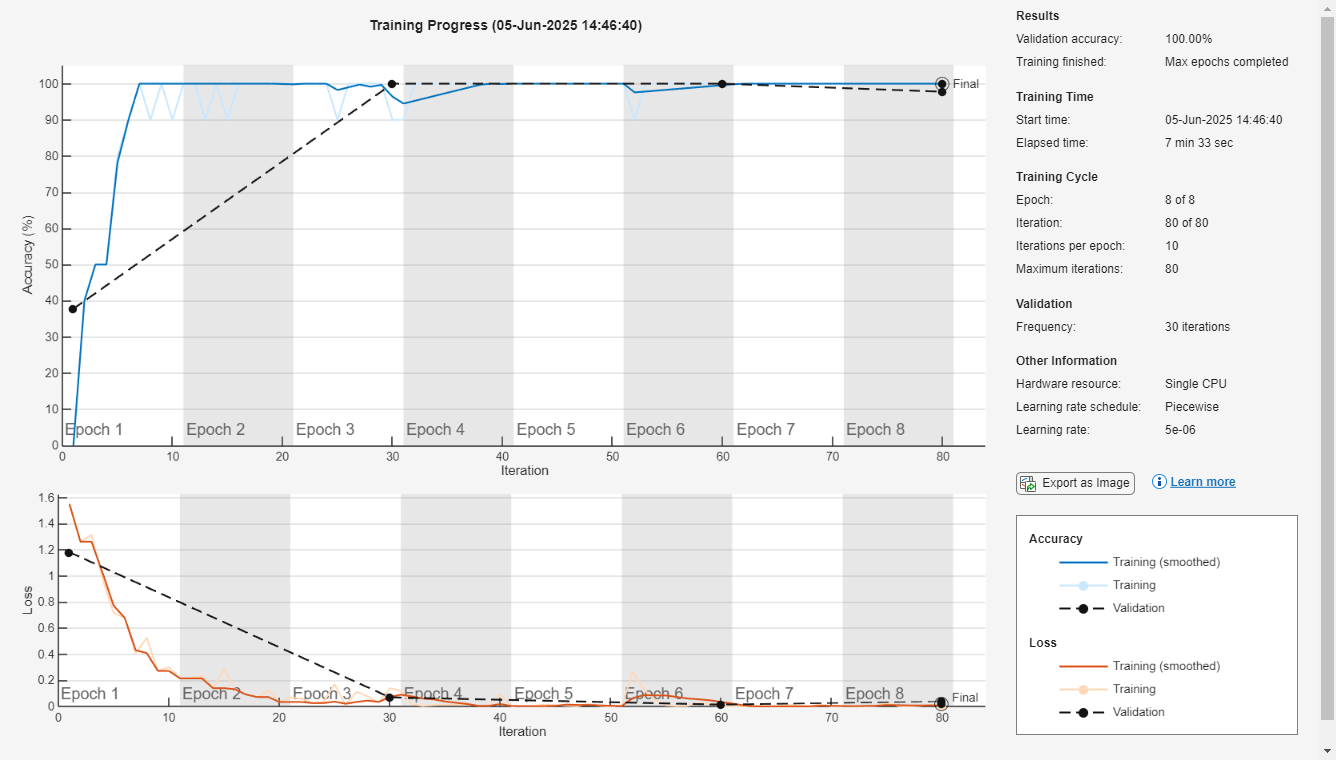

trainedNet =   DAGNetwork with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'new_output'}


trainInfo = struct with fields:
               TrainingLoss: [1.5502 1.2608 1.3126 0.9732 0.7164 0.6780 0.4086 0.5256 0.2720 0.3014 0.2147 0.2177 0.2329 0.1397 0.2824 0.1313 0.0904 0.0719 0.1230 0.0340 0.0688 0.0593 0.0256 0.0343 0.1683 0.0115 0.1124 0.0770 0.0292 … ] (1×80 double)
           TrainingAccuracy: [0 40 50 50 80 90 100 90 100 90 100 100 90 100 90 100 100 100 100 100 100 100 100 100 90 100 100 100 100 90 90 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 90 100 100 100 … ] (1×80 double)
             ValidationLoss: [1.1806 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 0.0696 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×80 double)
         ValidationAccuracy: [37.7778 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 100 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 

[trainedNet, trainInfo] = trainNetwork(augimdsTrain, lgraph, options)

**Save trained model (RUN AFTER TRAINING)**

save('model.mat', 'trainedNet', 'inputSize');